# Build Manipulator Robot Using Kinematic DH Parameters

The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

Parameters for the 5-axis SCORBOT robot as a matrix. Values come from .

dhparams = [1.2/100   	pi/2	36.4/100   	0;
            22/100	    0       0           0
            22/100	    0	    0	        0;
            0   	    pi/2	0	        0;
            0           0	    15/100   	0]

dhparams =     0.0120    1.5708    0.3640         0
    0.2200         0         0         0
    0.2200         0         0         0
         0    1.5708         0         0
         0         0    0.1500         0



% home position parameters
desired = [169/1000 0 503/1000]

desired =     0.1690         0    0.5030


Create a rigid body tree object.

robot = rigidBodyTree;

Create a cell array for the rigid body object, and another for the joint objects. Iterate through the DH parameters performing this process:

- Create a `rigidBody` object with a unique name.

- Create and name a revolute `rigidBodyJoint` object.

- Use `setFixedTransform` to specify the body-to-body transformation of the joint using DH parameters. The function ignores the final element of the DH parameters, `theta`, because the angle of the body is dependent on the joint position.

- Use `addBody` to attach the body to the rigid body tree.

bodies = cell(5,1);
joints = cell(5,1);
for i = 1:5
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    setFixedTransform(joints{i},dhparams(i,:),"dh");
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot,bodies{i},"base");
    else % Add current body to previous body by name
        addBody(robot,bodies{i},bodies{i-1}.Name);
    end
end


Verify that your robot has been built properly by using the `showdetails` or `show` function. The `showdetails` function lists all the bodies of the robot in the MATLAB® command window. The `show` function displays the robot with a specified configuration (home by default).

showdetails(robot);

--------------------
Robot: (5 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   
--------------------


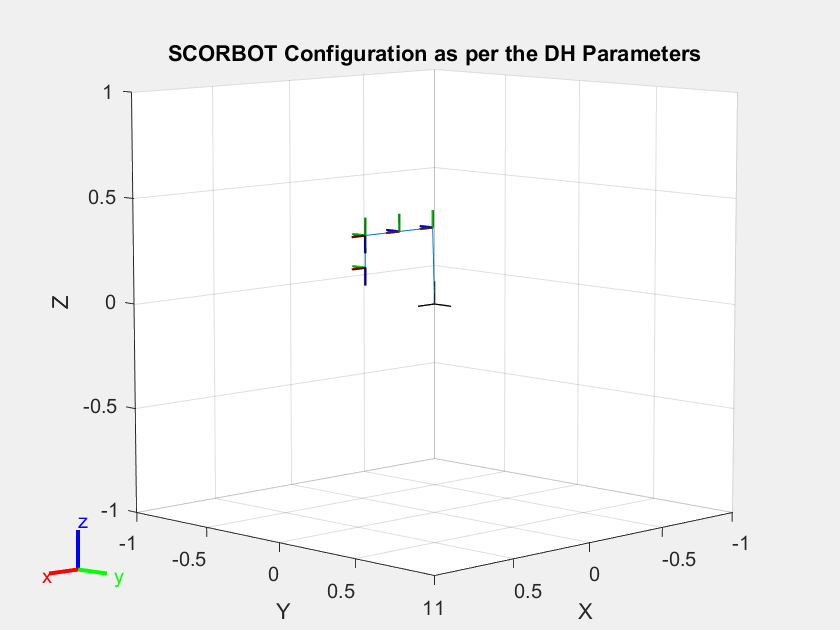

figure(Name="SCORBOT Robot Model")
show(robot);
title('SCORBOT Configuration as per the DH Parameters')

## Inverse Kinematics

Calculating the joint angles as per the desired location of end effector

desired location is defined above. It is same as the Home Position of actual SCORBOT Robot

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 1];
endEffector = 'body5';
[qSol, qInfo] = ik(endEffector,trvec2tform(desired),weights,q0)

qSol = 1×5 struct array with fields:
    JointName
    JointPosition


qInfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6422e-09
             ExitFlag: 1
               Status: 'success'


displaying the robot orientation as per the desired location of end effector

showdetails(robot);

--------------------
Robot: (5 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   
--------------------


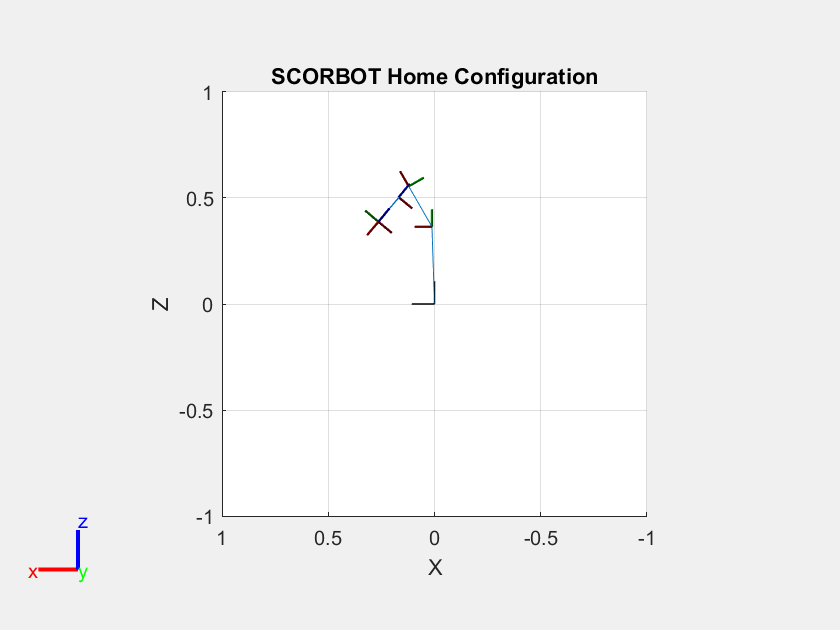

figure(Name="SCORBOT Robot Home")
show(robot, qSol);
view([180, 0]);
ax = gca;
ax.Projection = 'orthographic';
title('SCORBOT Home Configuration')